# Matlab model for image processing on FPGA

YCbCr to RGB conversion, tresholding, center of mass

## Floating point model

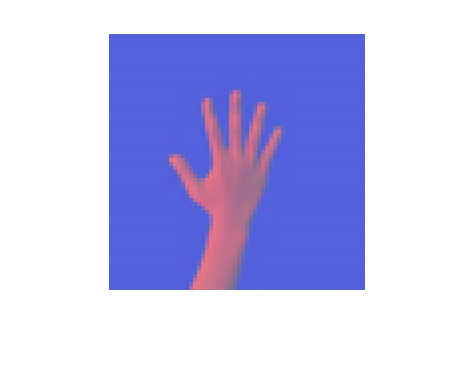

clear all
hand = imread('hand.jpg');         %read jpg
hand_64 = imresize(hand, [64 64]); %resize
imwrite(hand_64, 'hand_64.jpg')
hand_ycbcr = RGB2YCbCr(hand_64);   %conversion (not using the built-in conversion
                                   %due to different coef values
imshow(hand_ycbcr, 'InitialMagnification', 400)

colorThresholder(hand_ycbcr);     %uncomment to run, choose appropriate values

%imwrite(BW, "hand_BM.png");       %save image

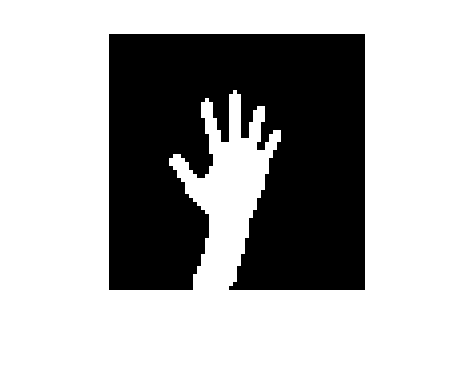

hand_BM = imread("hand_BM.png");   %read the binary image
hand_MF = medfilt2(hand_BM, [3 3]);%filer
figure
imshow(hand_MF, 'InitialMagnification', 400)

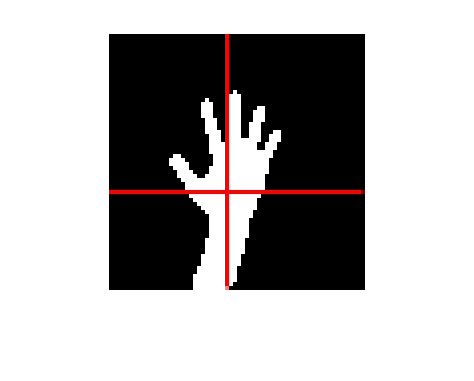

%find the center of mass
[x, y] = meshgrid(1:size(hand_MF, 2), 1:size(hand_MF, 1));
weightedx = x .* hand_MF;
weightedy = y .* hand_MF;
xcentre = sum(weightedx(:)) / sum(hand_MF(:));
ycentre = sum(weightedy(:)) / sum(hand_MF(:));

hand_ok = 255 * repmat(uint8(hand_MF), 1, 1, 3);
%draw the center of mass
hand_CM = insertShape(hand_ok, 'line', [xcentre 0 xcentre 64], 'Color', 'r');
hand_CM = insertShape(hand_CM, 'line', [0 ycentre 64 ycentre], 'Color', 'r');
figure
imshow(hand_CM, 'InitialMagnification', 400)

## Fixed point model

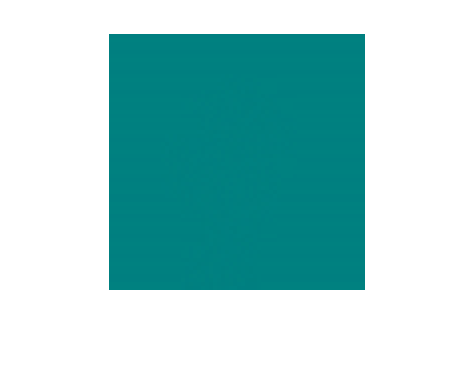

clear all
hand = imread('hand.jpg');         %read jpg
hand_64 = imresize(hand, [64 64]); %resize

hand_ycbcr = RGB2YCbCr_fi(hand_64);%conversion (not using the built-in conversion
                                   %due to different coef values

figure
imshow(cast(hand_ycbcr, 'uint8'), 'InitialMagnification', 400)

A = fi([[0.299 0.587 0.114];
     [-0.168736 -0.331264 0.5];
     [0.5 -0.418688 -0.081312]], 1, 18, 17);

B = fi([0; 128; 128], 1, 9, 0);

disp(hex(A))

09917   12c8b   03a5e
3a99b   35665   10000
10000   329a2   3d65e


disp(bin(B))

000000000
010000000
010000000


%--------------------------FLOATING POINT CONVERSION------------------------
%single pixel conversion
function [out_pix] = RGB2YCbCr_pix(input)
    A = [[0.299 0.587 0.114];      %coef matrix
         [-0.168736 -0.331264 0.5];
         [0.5 -0.418688 -0.081312]];
    B = [0; 128; 128];
    x = double(input(:,:)');
    out_pix = A*x + B;
end %RGB2YCbCr_pix

%whole image vonversion using single pixel conversion
function [out_img] = RGB2YCbCr(in_img)
out_img = zeros(size(in_img));
for i = 1:64
    for j = 1:64
        out_img(i, j, :) = RGB2YCbCr_pix(in_img(i, j, :));
    end %for
end %for
out_img = cast(out_img, 'uint8');
end %RGB2YCbCr


%-------------------------FIXED POINT CONVERSION----------------------------
function [out_pix] = RGB2YCbCr_pix_fi(input)
    a = fi([], 1, 18, 17);
    A_float = [[0.299 0.587 0.114];      %coef matrix
         [-0.168736 -0.331264 0.5];
         [0.5 -0.418688 -0.081312]];
    A = cast(A_float, 'like', a);        %fixed point coef matrix
    rgb = fi([], 1, 9, 0);
    B_float = [0; 128; 128];
    B = cast(B_float, 'like', rgb);
    x = double(input(:,:)');
    X = cast(x, 'like', rgb);              %fixed point RGB image
    out_pix = A*x;
    q = fixed.Quantizer;
    out_pix = quantize(q, out_pix);
    out_pix = out_pix + B;
end %RGB2YCbCr_pix_fi

%whole image vonversion using single pixel conversion
function [out_img] = RGB2YCbCr_fi(in_img)
    rgb = fi([], 1, 9, 0);
    out_img = zeros(size(in_img), 'like', rgb);
    for i = 1:64
        for j = 1:64
            out_img(i, j, :) = RGB2YCbCr_pix_fi(in_img(i, j, :));
        end %for
    end %for
end %RGB2YCbCr_fi